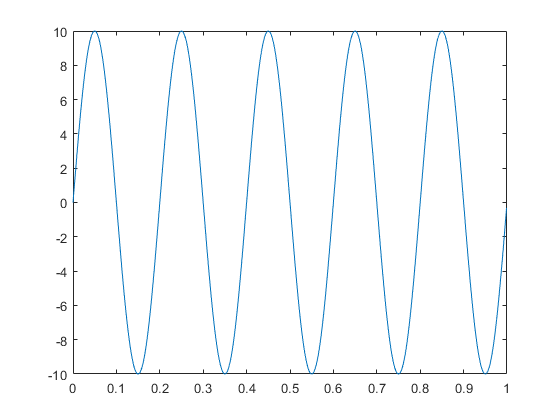

%zad1
fs=5;
A=10;
t=(0:0.001:0.999);
y1=A*sin(2*pi*fs*t);
plot(t,y1);

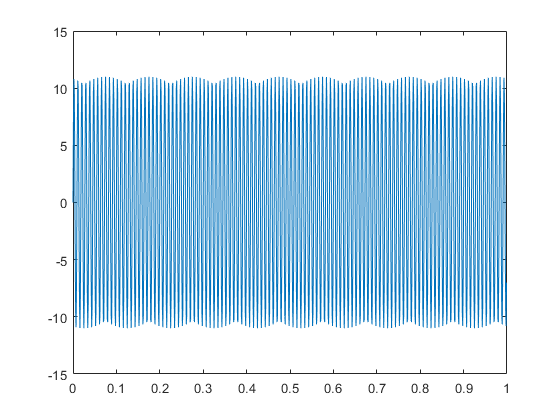

%zad2
f1=10;
f2=100;
A1=10;
A2=1;
t=(0:0.001:0.999);
y12=(A1+A2)*sin(2*pi*(f1+f2)*t);
plot(t,y12);

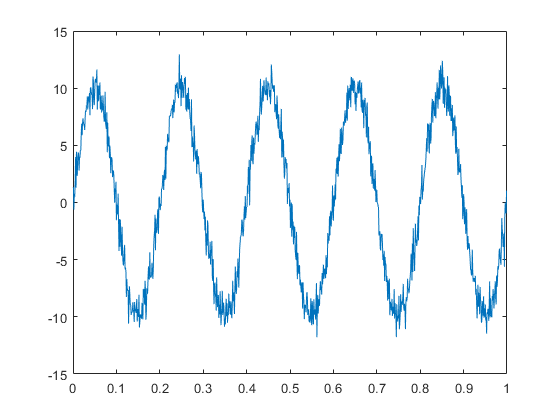

%zad3
yn= y1 + randn(size(t));
plot(t,yn);

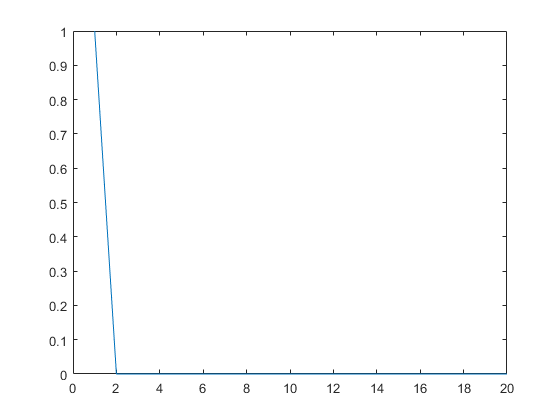

%zad4
imp= [1 zeros(1,19)];
plot(imp);

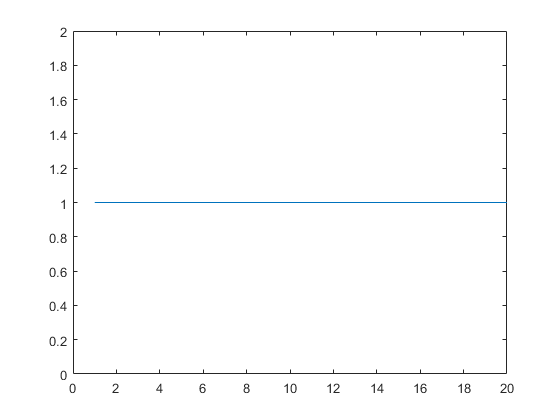

okno=ones(1,20);
plot(okno);

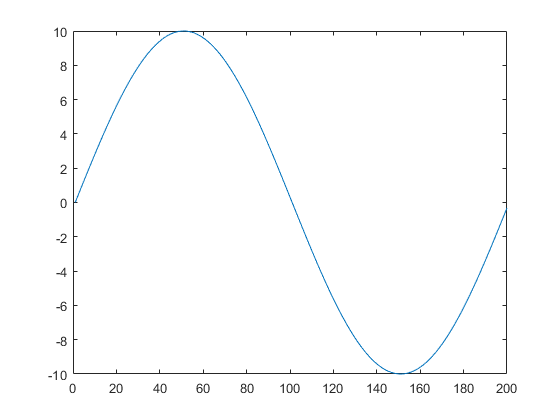

okres=y1(1:200);
plot(okres);

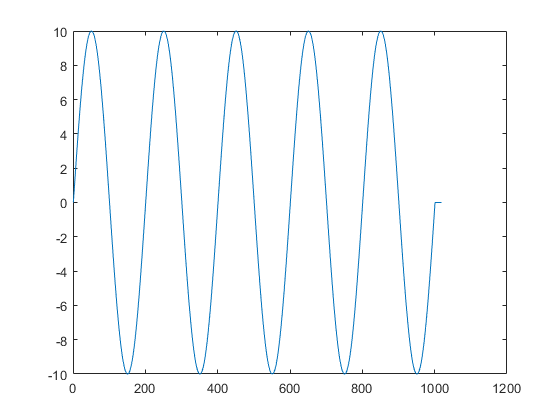

%zad5
y1_imp=conv(y1,imp);
plot(y1_imp);

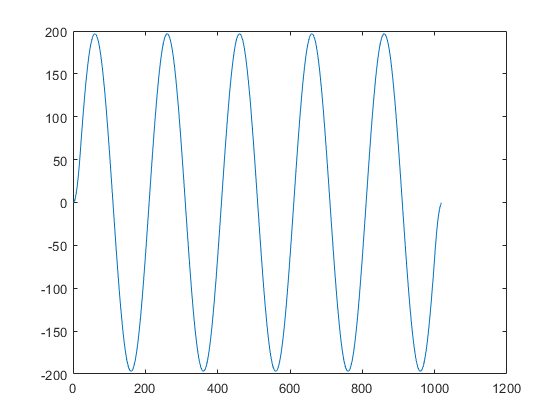

y1_okno= conv(y1,okno);
plot(y1_okno);

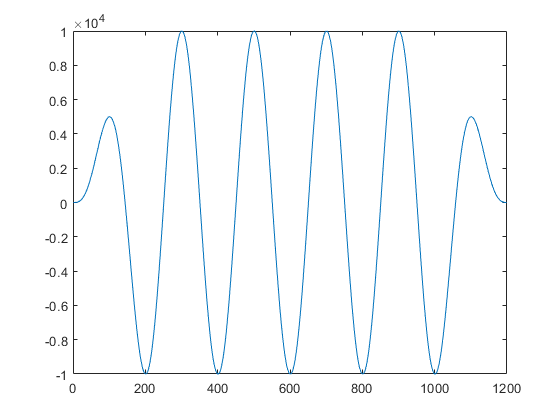

y1_okres= conv(y1,okres);
plot(y1_okres);

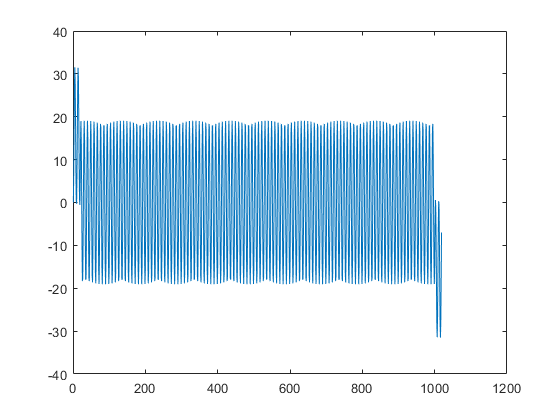

%zad6
y12_okno=conv(y12,okno);
plot(y12_okno);

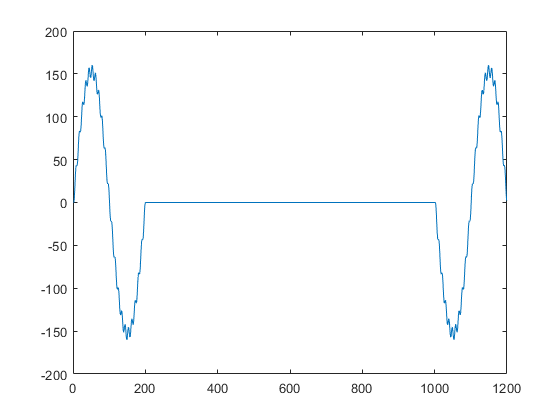

y12_okres=conv(y12,okres);
plot(y12_okres);

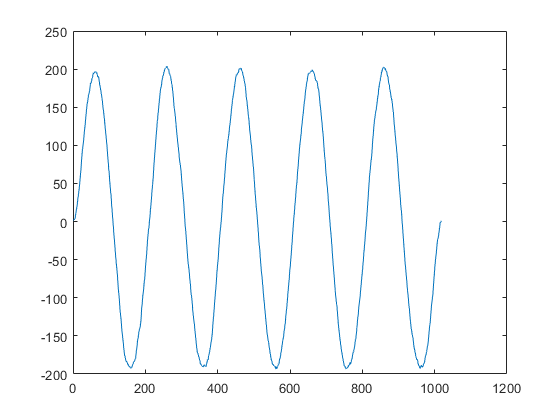

yn_okno=conv(yn,okno);
plot(yn_okno);

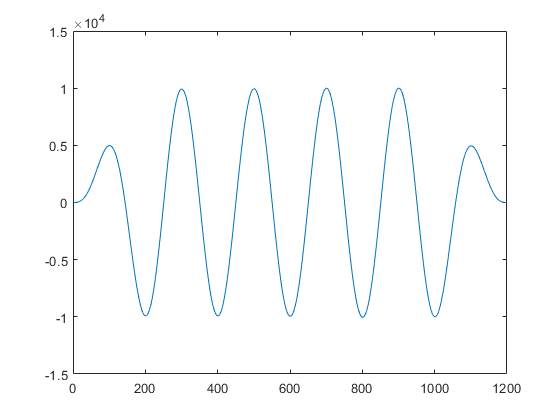

yn_okres=conv(yn,okres);
plot(yn_okres);

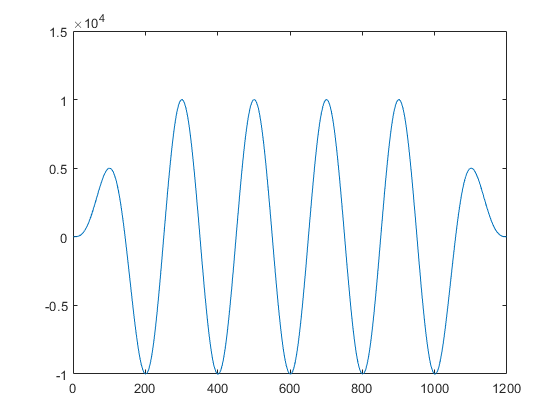

%zad7
x=y1;
h=okres;
yC=ifft(fft([x zeros(1,length(h)-1)]).*fft([h zeros(1,length(x)-1)]));
plot(yC);

x=y1;
j=okno;
yV=ifft(fft([x zeros(1,length(j)-1)]).*fft([j zeros(1,length(x)-1)]));
plot(yV);

q=y12;
j=okno;
yB=ifft(fft([q zeros(1,length(j)-1)]).*fft([j zeros(1,length(q)-1)]));
plot(yB);

q=y12;
h=okres;
yN=ifft(fft([q zeros(1,length(h)-1)]).*fft([h zeros(1,length(q)-1)]));
plot(yN);

e=yn;
h=okres;
yA=ifft(fft([e zeros(1,length(h)-1)]).*fft([h zeros(1,length(e)-1)]));
plot(yA);

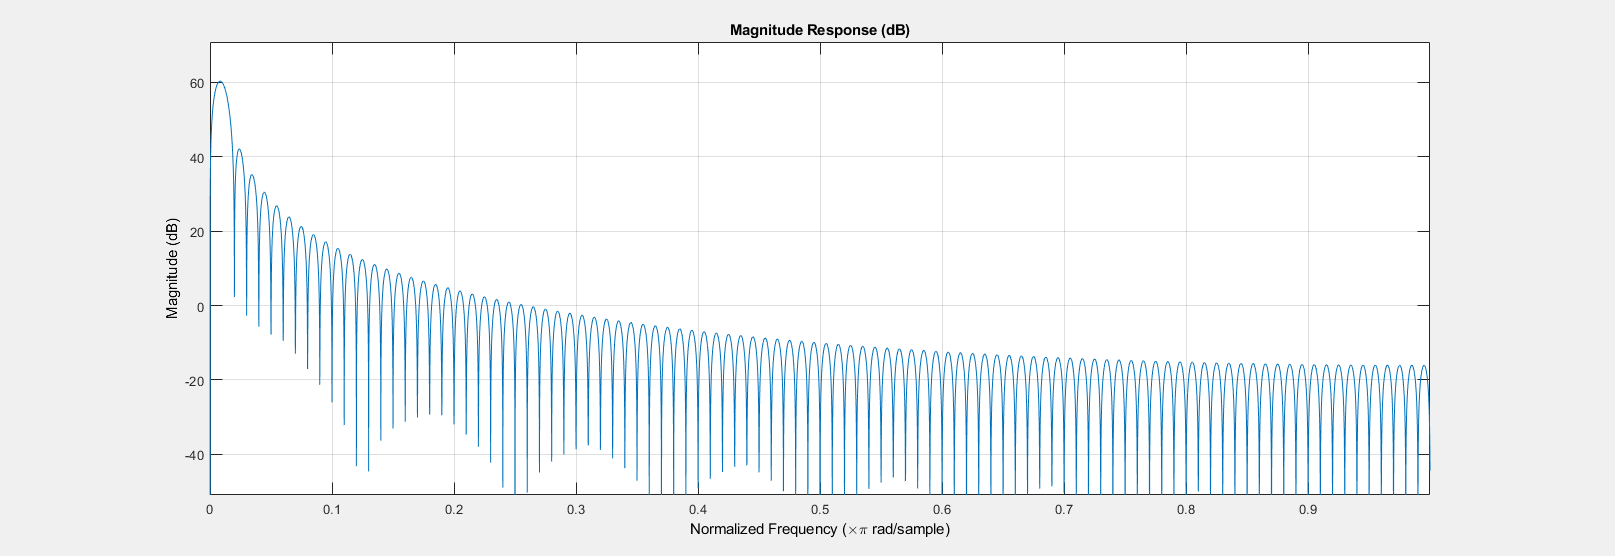

e=yn;
j=okno;
yM=ifft(fft([e zeros(1,length(j)-1)]).*fft([j zeros(1,length(e)-1)]));
plot(yM);

%zad8
fvtool(okres);

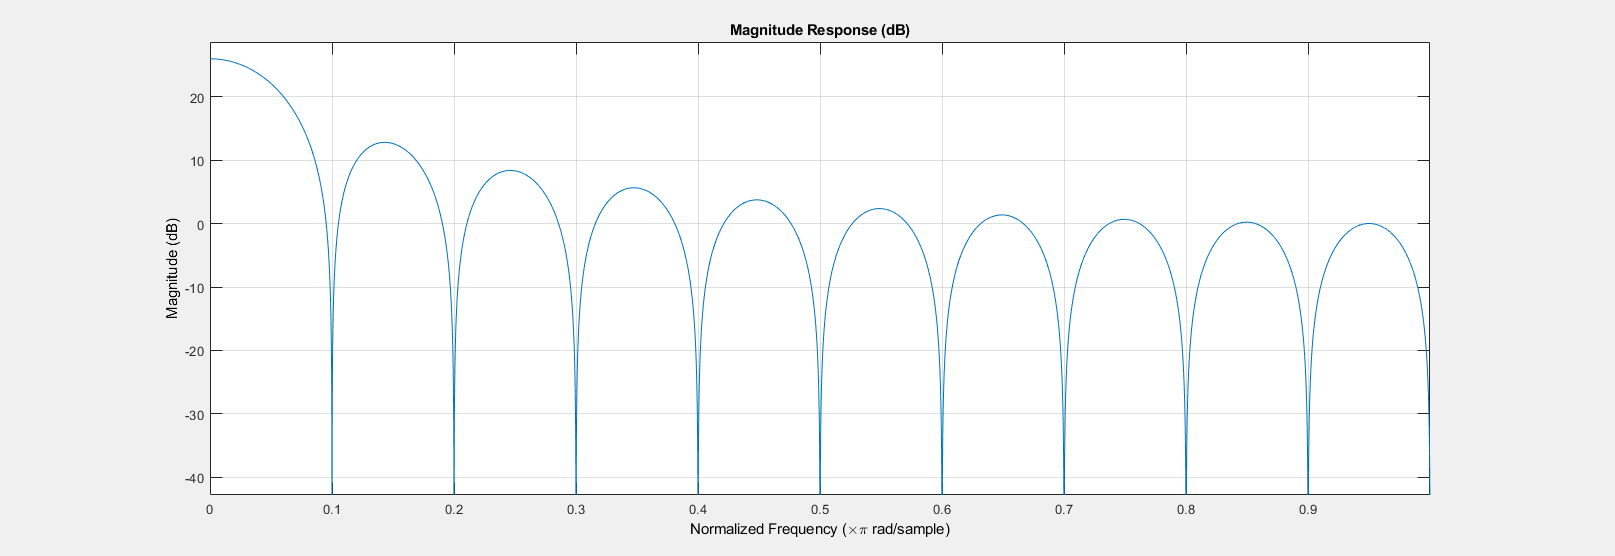

fvtool(okno);